# Ejercicio 4.01  

Usa la Robotics System Toolbox v2.2

Cargamos la cinemática del robot ABB irb-120:

kin_irb120;

$$conf\_home = \left(\begin{array}{cccc} 0 & 0 & 1 & 374\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & 630\\ 0 & 0 & 0 & 1 \end{array}\right)$$

cargamos el sólido y lo visualizamos:

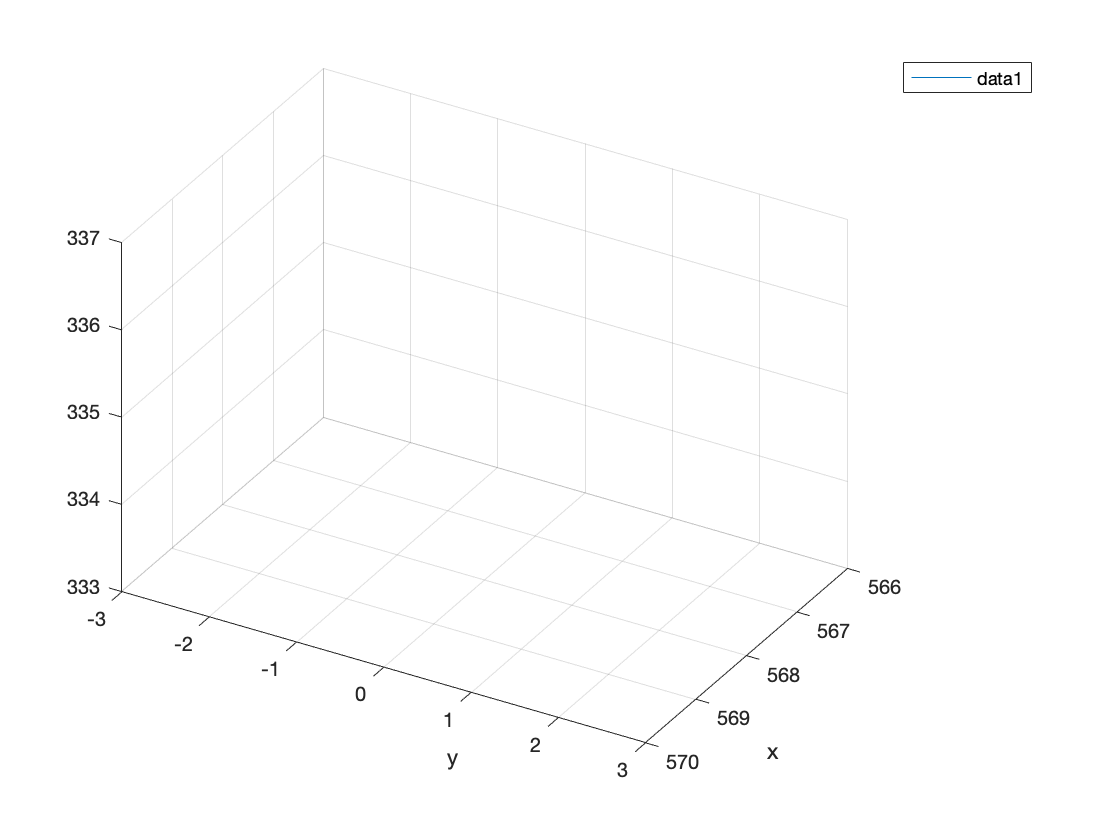

P=psolido;
Pp=P'; plot3(Pp(:,1),Pp(:,2)',Pp(:,3)')
axis equal; 
grid
view(120,30); hold on;
xlabel('x'); ylabel('y'); legend
axis([566 570 -3 3 333 337])

Hacemos tres giros respecto a X,Y,Z respectivamente.

% Giro 1:
%T1=axang2tform([1 0 0 pi/2])
q = [ 0 80 -80  0  90 0];
conf_home = round(subs(Tirb120,{t0, t1, t2, t3, t4, t5},{deg2rad(q(1)) , deg2rad(q(2)), deg2rad(q(3)), deg2rad(q(4)) , deg2rad(q(5)) , deg2rad(q(6)) }))

$$conf\_home = \left(\begin{array}{cccc} -1 & 0 & 0 & 568\\ 0 & 1 & 0 & 0\\ 0 & 0 & -1 & 335\\ 0 & 0 & 0 & 1 \end{array}\right)$$

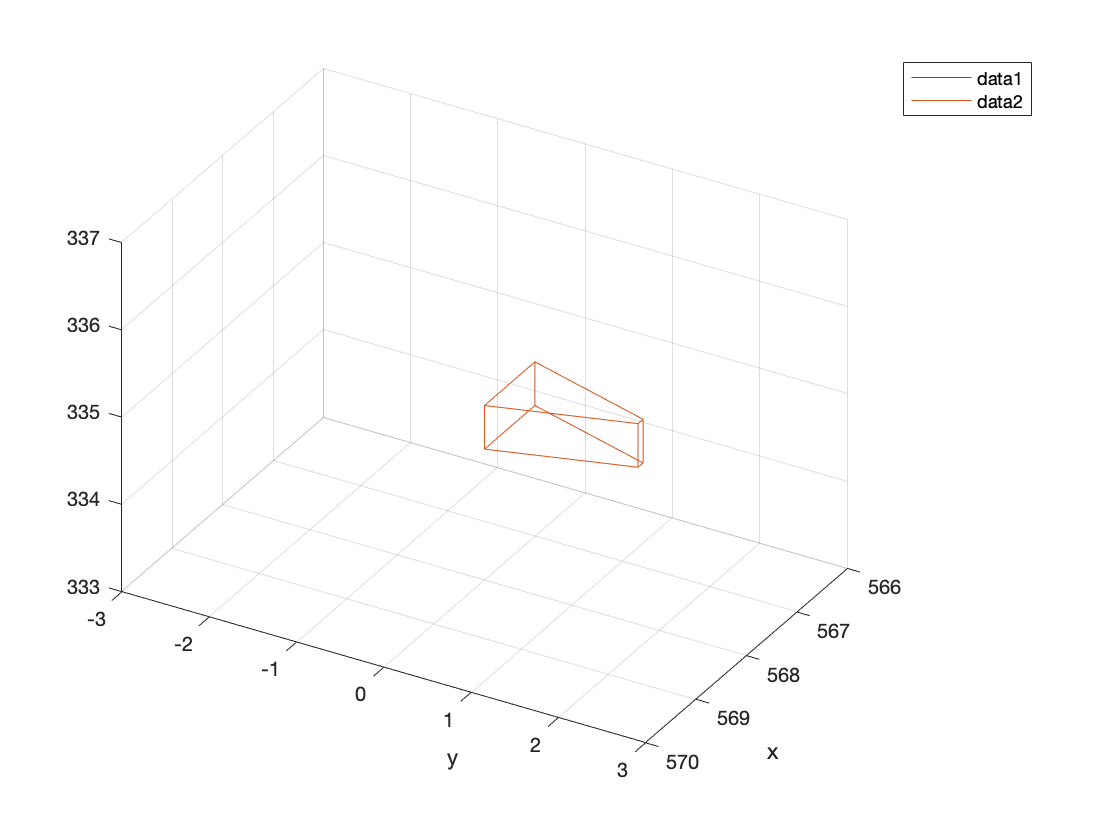

quat=tform2quat(double(conf_home));
T1=quat2tform(quat);
%quat = tform2quat(T1)

% en cartesianas:
% P = T1(1:3,1:3) * P;
% Pp=P'; plot3(Pp(:,1),Pp(:,2),Pp(:,3))

% en homogéneas:
% Los pasamos a coodenadas homogéneas:
Ph = cart2hom(P');
Ph=Ph';

Ph  = T1 * Ph;
Pp=Ph'; plot3(conf_home(1,4)+Pp(:,1),conf_home(2,4)+Pp(:,2),conf_home(3,4)+Pp(:,3))

%view([90.23 -0.00])

% Giro 2:
P=psolido;
%T1=axang2tform([0 1 0 pi/2]);
q = [ 0  80 -80 0 90 90];
conf_home = round(subs(Tirb120,{t0, t1, t2, t3, t4, t5},{deg2rad(q(1)) , deg2rad(q(2)), deg2rad(q(3)), deg2rad(q(4)) , deg2rad(q(5)) , deg2rad(q(6)) }))

$$conf\_home = \left(\begin{array}{cccc} 0 & 1 & 0 & 568\\ 1 & 0 & 0 & 0\\ 0 & 0 & -1 & 335\\ 0 & 0 & 0 & 1 \end{array}\right)$$

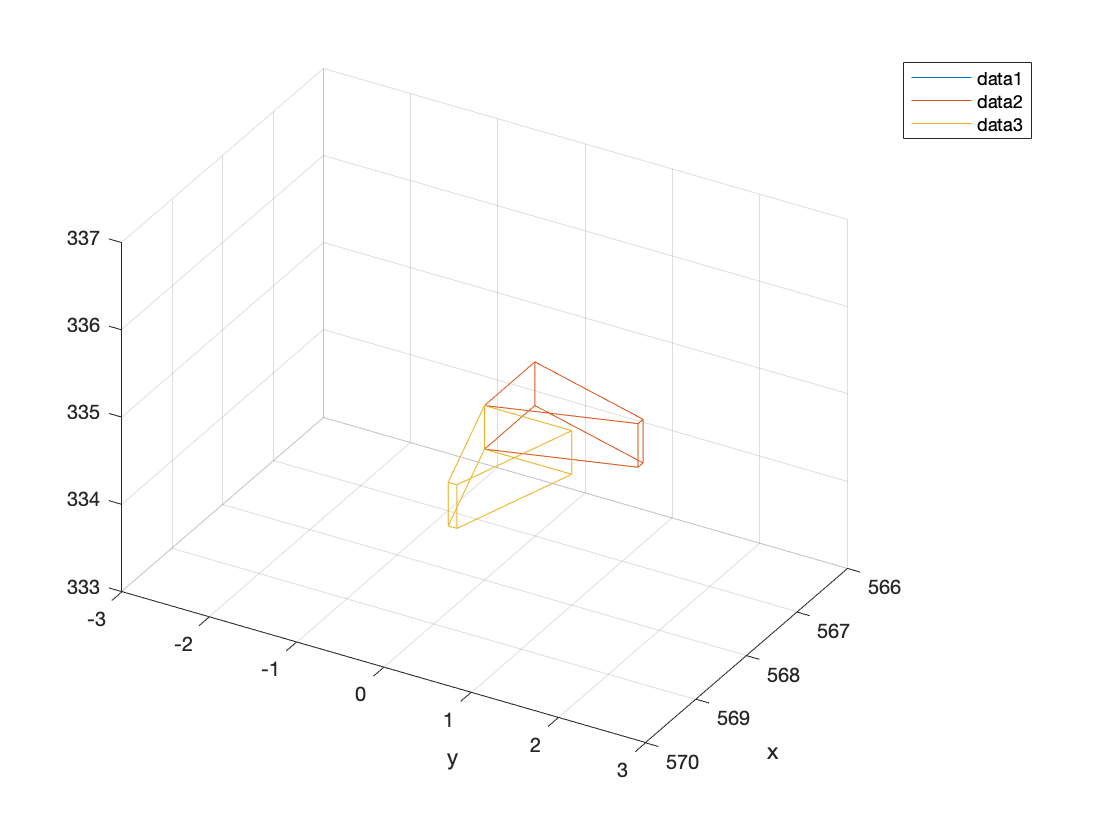

quat=tform2quat(double(conf_home));
T1=quat2tform(quat);
P = T1(1:3,1:3) * P;
Pp=P'; plot3(conf_home(1,4)+Pp(:,1),conf_home(2,4)+Pp(:,2),conf_home(3,4)+Pp(:,3))


%view([90.15 -0.00])
%quat = tform2quat(T1)


% Giro 3:
P=psolido;
%T1=axang2tform([0 0 1 pi/2]);
q = [ 0 80 -80  0  90 180];
conf_home = round(subs(Tirb120,{t0, t1, t2, t3, t4, t5},{deg2rad(q(1)) , deg2rad(q(2)), deg2rad(q(3)), deg2rad(q(4)) , deg2rad(q(5)) , deg2rad(q(6)) }))

$$conf\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & 568\\ 0 & -1 & 0 & 0\\ 0 & 0 & -1 & 335\\ 0 & 0 & 0 & 1 \end{array}\right)$$

quat=tform2quat(double(conf_home))

quat =      0     1     0     0


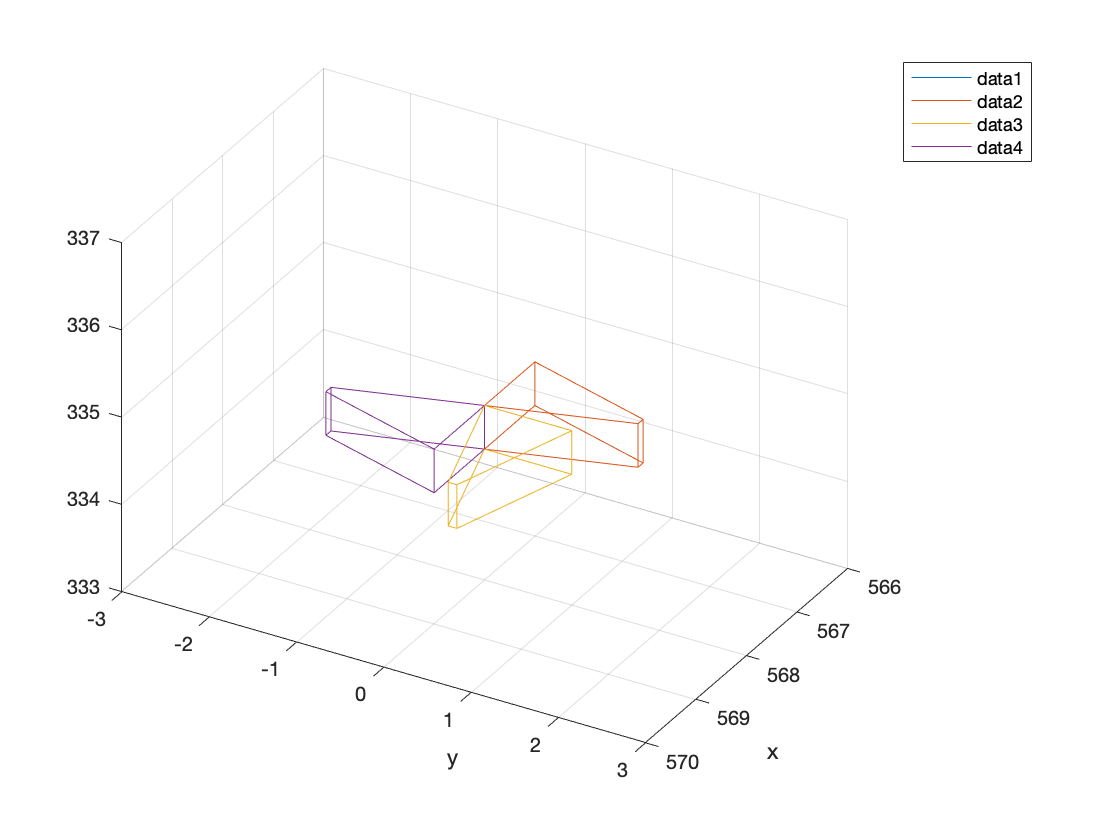

T1=quat2tform(quat);
P = T1(1:3,1:3) * P;
Pp=P'; plot3(conf_home(1,4)+Pp(:,1),conf_home(2,4)+Pp(:,2),conf_home(3,4)+Pp(:,3))

% Giro 4:
P=psolido;
%T1=axang2tform([0 0 1 pi/2]);
q = [ 0 80 -80 0 90 -90];
conf_home = round(subs(Tirb120,{t0, t1, t2, t3, t4, t5},{deg2rad(q(1)) , deg2rad(q(2)), deg2rad(q(3)), deg2rad(q(4)) , deg2rad(q(5)) , deg2rad(q(6)) }))

$$conf\_home = \left(\begin{array}{cccc} 0 & -1 & 0 & 568\\ -1 & 0 & 0 & 0\\ 0 & 0 & -1 & 335\\ 0 & 0 & 0 & 1 \end{array}\right)$$

quat=tform2quat(double(conf_home))

quat =          0   -0.7071    0.7071         0


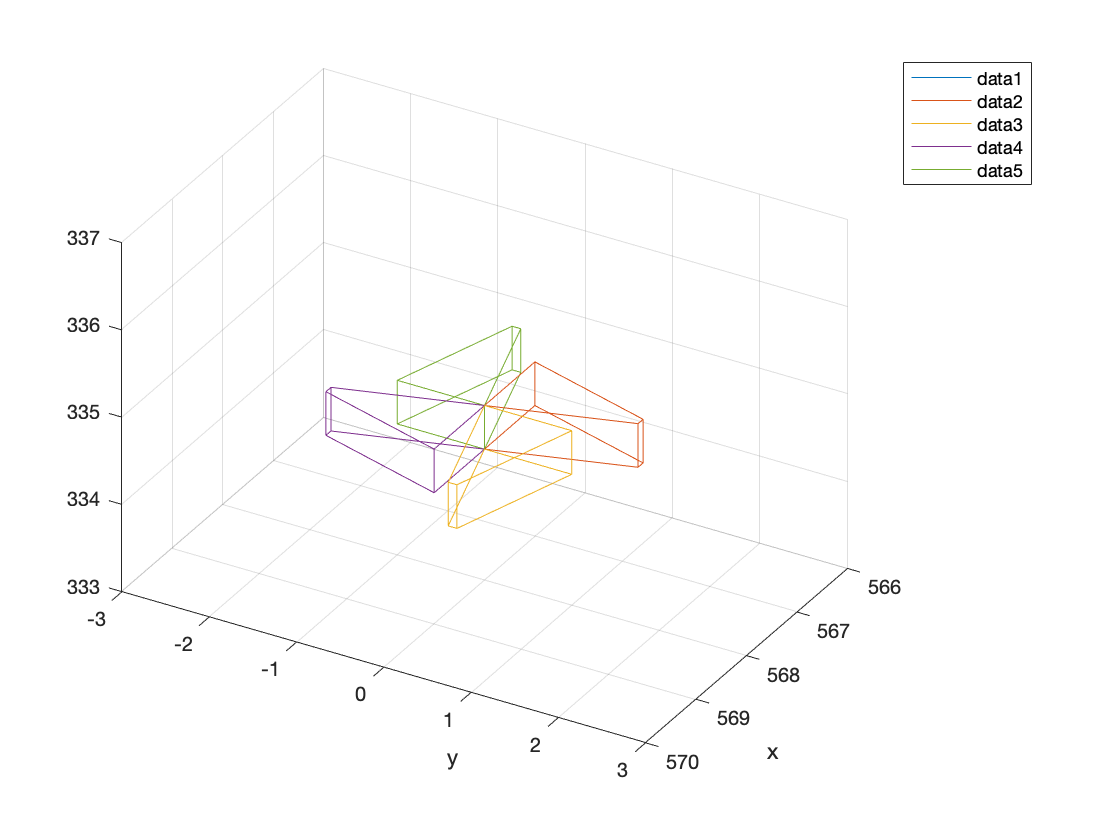

T1=quat2tform(quat);
P = T1(1:3,1:3) * P;
Pp=P'; plot3(conf_home(1,4)+Pp(:,1),conf_home(2,4)+Pp(:,2),conf_home(3,4)+Pp(:,3))